# Introduction to CANlab fMRI design tools

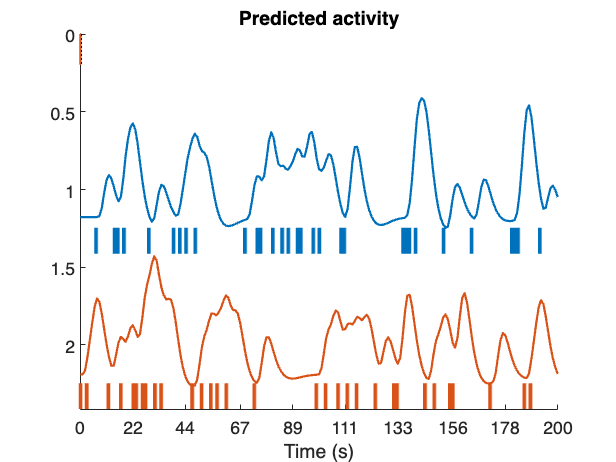


% optimizeGA, onsets2fmridesign, plotDesign, onsets2power, onsets2efficiency, onsets2singletrial
% create_block_design, create_design_single_event, create_random_er_design, create_random_onsets
% calcEfficiency
% tor_make_deconv_mtx3

TR = 1;
ISI = 1.3;
[X, e, onsets] = create_random_er_design(TR, ISI, 1, [.2 .2], 180, 0);

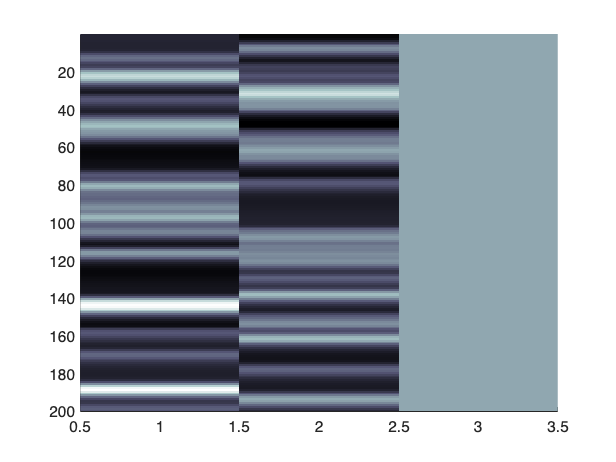


create_figure('X'); imagesc(X); set(gca, 'YDir', 'Reverse'); axis tight; colormap bone

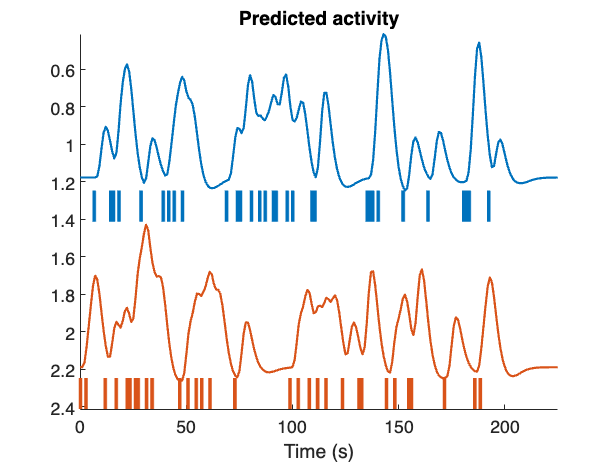


[X,d,out,handles] = plotDesign(onsets,[],TR);


colors = {get(handles(1), 'Color')  get(handles(2), 'Color')};


% colors = seaborn_colors(4);
% set(handles(1), 'color', colors{1});
% set(handles(2), 'color', colors{2});


create_figure('FFT')

ans =   Figure (FFT) with properties:

      Number: 45
        Name: 'FFT'
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


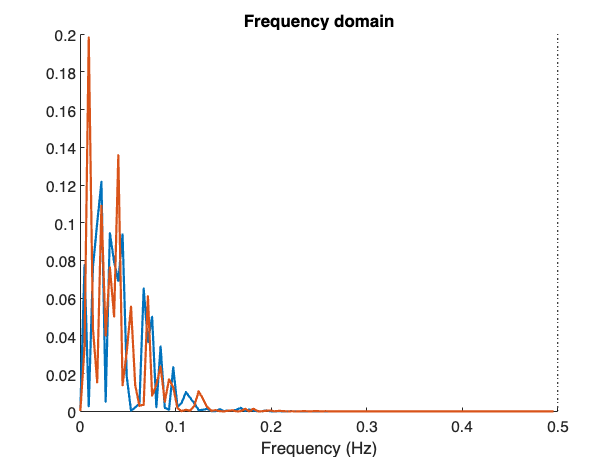


[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(X(:, 1), 1), TR);
set(line_handle, 'Color', colors{1})

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(X(:, 2), 1), TR);
set(line_handle, 'Color', colors{2})

% simulate noise, with cardiac element

theta = 0;             % Phase, in radians
F = 1;                 % Frequency of sin wave (cycles/sec)
T = 0.001;             % Time resolution in sec; time between high-frequency samples
scanlen = size(X, 1) .* TR;
t = 0:0.001:(scanlen-0.001);        % Vector of sample times for all samples (10 sec sampling duration)

y = sin(2 * pi * F * t + theta);

e = noise_arp(length(y));

downsample_by = round((1/T) / (1/TR))

downsample_by = 1000

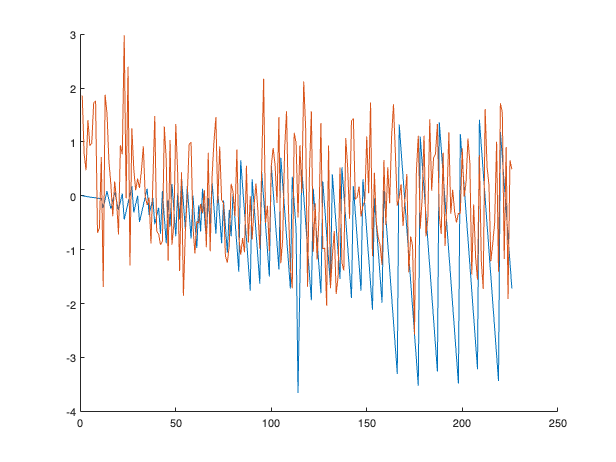


y_tr = y(1:downsample_by:end);
y_tr = y_tr' ./ std(y_tr);

e_tr = e(1:downsample_by:end);
e_tr = e_tr ./ std(e_tr);

figure; hold on; plot(y_tr); plot(e_tr)

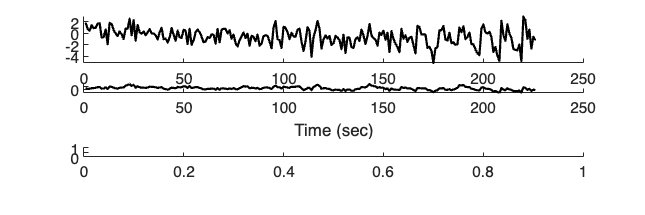


noisevec = y_tr + e_tr;

create_figure('signal and noise', 3, 1); hold on; set(gca, 'FontSize', 14)
plot(noisevec, 'k', 'LineWidth', 2)

subplot(3, 1, 2); set(gca, 'FontSize', 14)
datavec = 2 .* X(:, 1) + 1 * X(:, 2) + noisevec;

plot(datavec, 'k', 'LineWidth', 2)
xlabel('Time (sec)')


create_figure('fft')

ans =   Figure (fft) with properties:

      Number: 81
        Name: 'fft'
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


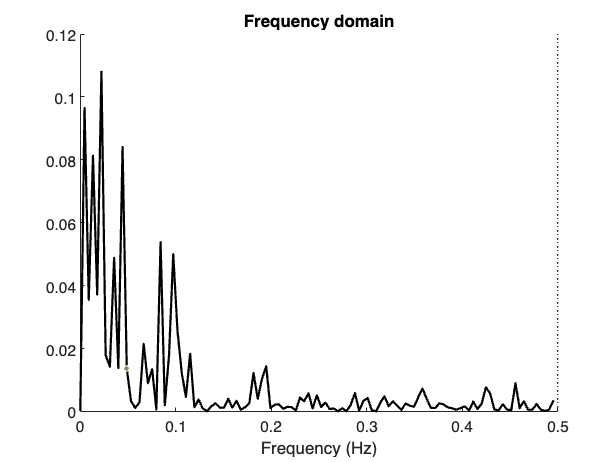

[myfft, freq, line_handle, nyquist_line_handle] = fft_calc(scale(datavec, 1), TR);
set(line_handle, 'Color', 'k')